%dft

xn=input('Enter x : ');
N=input('Number of DFT points : ');
m=length(xn);
xn=[xn zeros(1,N-m)];
xk=zeros(1,N);
for k=1:N
for n=1:N
xk(k)=xk(k)+xn(n)*exp((-1j*2*pi*(k-1)*(n-1))/N);
end
end
disp("DFT: ");

DFT: 


disp(xk);

  19.0000 + 0.0000i  -3.9271 -11.3597i  -0.5729 + 3.4940i  -0.5729 - 3.4940i  -3.9271 +11.3597i



t=0:N-1;
subplot(2,2,1);
stem(t,xn);
title('x(n)');
xlabel('Time');
ylabel('Amplitude');
subplot(2,2,2);
stem(t,xk);

title('X(k)');
xlabel('Time');
ylabel('Amplitude');
mag=abs(xk);
disp("Magnitude value : ");

Magnitude value : 


disp(mag);

   19.0000   12.0193    3.5406    3.5406   12.0193



subplot(2,2,3);
stem(t,mag);
title('Magnitude response');
xlabel('Time');
ylabel('Magnitude');
phase=angle(xk);
disp("Phase value : ");

Phase value : 


disp(phase);

         0   -1.9036    1.7333   -1.7333    1.9036



subplot(2,2,4);
stem(t,phase);
title('Phase response');
xlabel('Time');
ylabel('Phase');


%IDFT
Xk=input('Enter X[k]: ');
N=length(Xk);
xn=zeros(1,N);
for n=1:N
for k=1:N
xn(n)=xn(n)+Xk(k)*exp((1j*2*pi*(n-1)*(k-1))/N);
end
xn(n)=xn(n)/N;
end
disp("IDFT value :");

IDFT value :


disp(xn);

   4.7500 + 0.0000i  -1.7500 + 1.5000i   0.7500 - 0.0000i  -1.7500 - 1.5000i



t=0:N-1;
subplot(2,2,1);
stem(t,Xk);
title('X(k)');
xlabel('Time');
ylabel('Amplitude');
subplot(2,2,2);
stem(t,xn);

title('x(n)');
xlabel('Time');
ylabel('Amplitude');
mag=abs(xn);
disp("Magnitude value :");

Magnitude value :


disp(mag);

    4.7500    2.3049    0.7500    2.3049



subplot(2,2,3);
stem(t,mag);
title('Magnitude response');
xlabel('Time');
ylabel('Magnitude');
phase=angle(xn);
disp("Phase value :");

Phase value :


disp(phase);

         0    2.4330   -0.0000   -2.4330



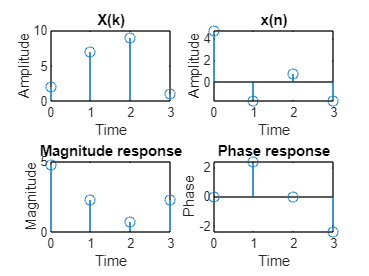

subplot(2,2,4);
stem(t,phase);
title('Phase response');
xlabel('Time');
ylabel('Phase');